## Set up the Import Options and import the data

opts = delimitedTextImportOptions("NumVariables", 26);

% Specify range and delimiter
opts.DataLines = [1, Inf];
opts.Delimiter = " ";

% Specify column names and types
opts.VariableNames = ["VarName1", "VarName2", "VarName3", "VarName4", "VarName5", "VarName6", "VarName7", "VarName8", "VarName9", "VarName10", "VarName11", "VarName12", "VarName13", "VarName14", "VarName15", "VarName16", "VarName17", "VarName18", "VarName19", "VarName20", "VarName21", "VarName22", "VarName23", "VarName24", "VarName25", "VarName26"];
opts.VariableTypes = ["double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double"];

% Specify file level properties
opts.ExtraColumnsRule = "ignore";
opts.EmptyLineRule = "read";
opts.ConsecutiveDelimitersRule = "join";
opts.LeadingDelimitersRule = "ignore";

% Import the data
% training data
trainFD001 = readtable("C:\Users\chant\OneDrive\Desktop\Course Materials\ADAML\Project Work - 01102023\train_FD001.txt", opts);
trainFD002 = readtable("C:\Users\chant\OneDrive\Desktop\Course Materials\ADAML\Project Work - 01102023\train_FD002.txt", opts);
trainFD003 = readtable("C:\Users\chant\OneDrive\Desktop\Course Materials\ADAML\Project Work - 01102023\train_FD003.txt", opts);
trainFD004 = readtable("C:\Users\chant\OneDrive\Desktop\Course Materials\ADAML\Project Work - 01102023\train_FD004.txt", opts);

% testing data
testFD001 = readtable("C:\Users\chant\OneDrive\Desktop\Course Materials\ADAML\Project Work - 01102023\test_FD001.txt", opts);
testFD002 = readtable("C:\Users\chant\OneDrive\Desktop\Course Materials\ADAML\Project Work - 01102023\test_FD002.txt", opts);
testFD003 = readtable("C:\Users\chant\OneDrive\Desktop\Course Materials\ADAML\Project Work - 01102023\test_FD003.txt", opts);
testFD004 = readtable("C:\Users\chant\OneDrive\Desktop\Course Materials\ADAML\Project Work - 01102023\test_FD004.txt", opts);

% RUL for testing data
RULFD001 = readtable("C:\Users\chant\OneDrive\Desktop\Course Materials\ADAML\Project Work - 01102023\RUL_FD001.txt", opts);
RULFD002 = readtable("C:\Users\chant\OneDrive\Desktop\Course Materials\ADAML\Project Work - 01102023\RUL_FD002.txt", opts);
RULFD003 = readtable("C:\Users\chant\OneDrive\Desktop\Course Materials\ADAML\Project Work - 01102023\RUL_FD003.txt", opts);
RULFD004 = readtable("C:\Users\chant\OneDrive\Desktop\Course Materials\ADAML\Project Work - 01102023\RUL_FD004.txt", opts);


## Convert to output type

trainFD001 = table2array(trainFD001);
trainFD002 = table2array(trainFD002);
trainFD003 = table2array(trainFD003);
trainFD004 = table2array(trainFD004);

testFD001 = table2array(testFD001);
testFD002 = table2array(testFD002);
testFD003 = table2array(testFD003);
testFD004 = table2array(testFD004);

RULFD001 = table2array(RULFD001);
RULFD002 = table2array(RULFD002);
RULFD003 = table2array(RULFD003);
RULFD004 = table2array(RULFD004);

## Clear temporary variables

clear opts
varN = ["VarName3", "VarName4", "VarName5", "VarName6", "VarName7", "VarName8", "VarName9", "VarName10", "VarName11", "VarName12", "VarName13", "VarName14", "VarName15", "VarName16", "VarName17", "VarName18", "VarName19", "VarName20", "VarName21", "VarName22", "VarName23", "VarName24", "VarName25", "VarName26"];

X1 = trainFD001 ; X2 = trainFD002; X3 = trainFD003; X4 = trainFD004;
X1(:,[1,2])=[]; X2(:,[1,2])=[]; X3(:,[1,2])=[]; X4(:,[1,2])=[];

model(1).data = trainFD001; model(2).data = trainFD002; model(3).data = trainFD003; model(4).data = trainFD004;
model(1).X = X1; model(2).X = X2; model(3).X = X3; model(4).X = X4;
model(1).y = GetRUL(trainFD001); model(2).y = GetRUL(trainFD002); model(3).y = GetRUL(trainFD003); model(4).y = GetRUL(trainFD004);

model(1).test = testFD001; model(2).test = testFD002; model(3).test = testFD003; model(4).test = testFD004;
model(1).RUL = RULFD001; model(2).RUL = RULFD002; model(3).RUL = RULFD003; model(4).RUL = RULFD004;


### **Exploratory Data Analysis**

% Create summary stats table for each training dataset.
for i = 1:4
    model(i).summary = CreateSummary(model(i).X, varN);
end

% Plot a box plot for each.
figure;
for i = 1:4
    subplot(2,2,i)
    boxplot(model(i).X)
    title('Boxplot showing Original Data ',num2str(i))
end

Remove single value columns from the data

for i = 1:4
    model(i).single_col = [];
    k = 1;
    for j = 1:length(model(i).X(1,:))
        if round(model(i).summary{j,"SD"},5) == 0
            model(i).single_col(k) = j;
            k = k+1;
        end
    end
    model(i).X(:,model(i).single_col) = [];
end


Normalize and revisualize

% Normalize each
for i = 1:4
    [model(i).Xnorm, model(i).C, model(i).S] = normalize(model(i).X);
end

% Plot a box plot for each normalized data.
figure;
for i = 1:4
    subplot(2,2,i)
    boxplot(model(i).Xnorm)
    title('Boxplot showing Normalized Data ',num2str(i))
end

Studying relationships between individual columns and the rul for a given number of units or any given unit. Code commented out because it takes long to run.

for i = 1:4
    model(i).unitnum = unique(model(i).data(:,1));
end


for unit = [1 4 5 100 10]
    figure;
    title(['Relationship between X and y for unit ', num2str(unit)]);
    [id1, ~] = find(model(1).data(:,1)==unit);
    for i = 1:length(model(1).X(1,:))
        subplot(6, 4, i)
        scatter(model(1).Xnorm(id1,i), model(1).y(id1))
    end
end


figure;
correlation = corr(model(1).Xnorm,model(1).Xnorm)

correlation =     1.0000    0.0117    0.0090   -0.0057    0.0095   -0.0013   -0.0094   -0.0004   -0.0043    0.0117   -0.0015    0.0023   -0.0045    0.0077    0.0026   -0.0057   -0.0146
    0.0117    1.0000    0.0073    0.0091    0.0147    0.0144   -0.0167    0.0133   -0.0054    0.0117   -0.0109    0.0182   -0.0063    0.0142    0.0123   -0.0106   -0.0078
    0.0090    0.0073    1.0000    0.6026    0.7149    0.1322   -0.7021    0.6623    0.2738    0.7400   -0.7246    0.6618    0.1798    0.6760    0.6299   -0.6618   -0.6681
   -0.0057    0.0091    0.6026    1.0000    0.6784    0.1160   -0.6646    0.6025    0.3230    0.6959   -0.6803    0.6010    0.2371    0.6399    0.6000   -0.6259   -0.6339
    0.0095    0.0147    0.7149    0.6784    1.0000    0.1505   -0.7931    0.7469    0.2974    0.8301   -0.8156    0.7452    0.1907    0.7585    0.7035   -0.7481   -0.7452
   -0.0013    0.0144    0.1322    0.1160    0.1505    1.0000   -0.1557    0.1522    0.0193    0.1600   -0.1559    0.1583   -0.0021 

heatmap(correlation)

% % for j=1:4
% %     figure;
% %     for i = 1:length(model(j).X(1,:))
% %         subplot(6, 4, i)
% %         scatter(model(j).X(:,i), model(j).y)
% %     end
% % end
% 

Is there any variable which characterises the early lifetime and later life time of a TurboFan Engine?

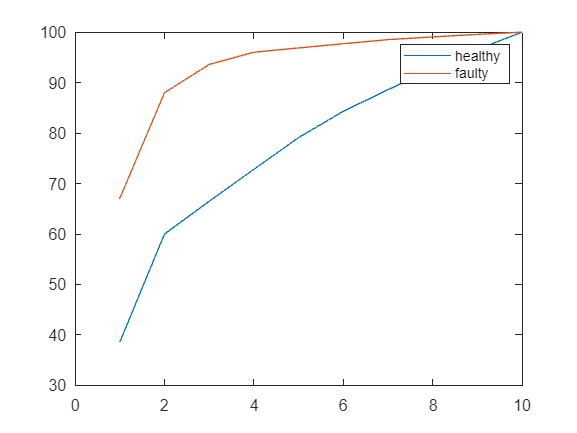

for i = 1:4
    for unit  = 1 %model(i).unitnum
        k=0;
        [id1, ~] = find(model(i).data(:,1)==unit);
        for j = 1:length(model(i).Xnorm(1,k+1:unit))
            model(i).early_life = model(i).y > mean(model(i).y) + 0;
        end
        k = k + unit;
    end
end

figure;
title('Relationship between some important pairs of variables and early life')
gplotmatrix(model(3).Xnorm(id1,[1 2 5 8 9 10 11 14 15 16 18]), [], model(3).early_life(id1));

PCA to see if there are any faulty data, especially for dataset 2 (-_-) ...because why are you so strange?

% [earlyidx, ~] = find(model(3).early_life==1);
% [lateidx, ~] = find(model(3).early_life==0);
% 
% healthy_ = model(3).X(earlyidx, :);
% [healthy, C, S] = zscore(healthy_);
% 
% faulty_ = model(3).X(lateidx, :);
% faulty = normalize(faulty_, "center", C, "scale", S);
% Compute PCA for healthy dataset
% [P, T, latent, tsq, expl] = ...
%     pca(healthy, 'Centered', false, 'NumComponents', 8);
% 
% [Pf, Tf, latentf, tsqf, explf] = ...
%     pca(faulty, 'Centered', false, 'NumComponents', 8);
% 
% 
% figure;
% a = plot(1:10, 100*cumsum(expl(1:10))/sum(expl(1:10)));
% hold on
% b = plot(1:10, 100*cumsum(explf(1:10))/sum(explf(1:10)));
% hold off
% legend([a, b], 'healthy','faulty')
% 
% figure;
% i = 7;
% subplot(1,2,1);
% biplot(P(:,i:i+1), 'Scores', T(:,i:i+1));
% subplot(1,2,2)
% biplot(Pf(:,i:i+1), 'Scores', Tf(:,i:i+1));


K-Fold Cross Validation

model(1).crossval = K_Fold(model(1).X, model(1).RUL, 10);

Unrecognized function or variable 'Test'.